# Graph Attributes

A benefit of working with MATLAB's builtin graph type is the ability to store additional information about the graphs in the object. Many of igraph's functions return a vector, and these vectors often map values to either nodes or edges. In this case, these are referred to as node or edge attributes. These can be attached directly to graphs represented using one of MATLAB's builtin graph classes.

Functions that accept an attribute can be passed the vector directly or can be passed a name of the node attribute if it's stored with the graph. As an example, centrality metrics return a measure for each node. In normal MATLAB programming style, the vector is returned as a separate object to work with and pass around:

g = igraph.famous("zachary");
betweenness = igraph.centrality(g, "betweenness")

betweenness =   231.0714   28.4786   75.8508    6.2881    0.3333   15.8333   15.8333         0   29.5294    0.4476    0.3333         0         0   24.2159         0         0         0         0         0   17.1468         0         0         0    9.3000    1.1667    2.0278         0   11.7921    0.9476    1.5429    7.6095   73.0095   76.6905  160.5516


The betweenness vector holds a value for each of the Zachary karate club graph's 34 nodes. Instead of getting a separate vector, the attribute can be attached to the graph's node table by passing a name for the results:

g = igraph.centrality(g, "betweenness", results="betweenness");
igraph.summary(g);


    Unweighted and Undirected igraph with:

     34 nodes
     78 edges
     0.13 edge density

    Node attributes:

     betweenness



Notice the centrality function returns a new graph object. The old graph is not changed so it must be overwritten.

Attributes names can then be used in place of the vectors. This provides a way to move around several pieces of data together. We can now reproduce one of the plots from the Getting Started livescripts using graph attributes:

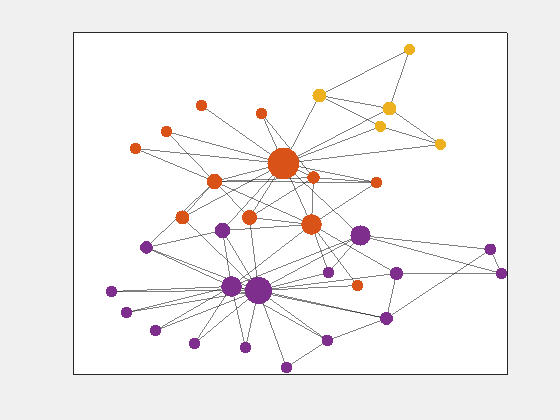

g = igraph.famous("zachary");
g = igraph.centrality(g, "betweenness", results="betweenness");
g = igraph.cluster(g, "infomap", results="membership");
igraph.plot(g, "kk", nodeColor="membership", size="betweenness")